# VARX Model 

## Setup

### Set paths

The VARX package is already included in this folder and will be added here:

addpath('../src/varx/matlab')

The up-to-date package, including versions in Python and R, is on github: [https://github.com/lcparra/varx](https://github.com/lcparra/varx) 

## Find another example! -> maybe the same two channels used below (3,93) and film cuts used below

## Add images of the model 

## Demo of VARX function 

This first example shows the basic usage of the varx() function on union participation and strike data in the US. 

### Background

Causal models are often employed in sociology. This example is motivated by work that has challenged the assumption that union membership provides resources for collective actions causing an increase the number of workers on strike. Alternatively, strikes could motivate more workers to join unions leading to an incrase in membership and thus provide benefits to unions even if demands to employers are not met (Hodder et al., 2016). Unemployment rate is included as an external variable. It is assumed that unemployment rate is not affected by union membership or number of workers on strike, but can influence either of these two variables. 

### Example

We will apply the VARX model on historical data of union membership, number of workers on strike and unemployment rate in the US. A more comprehensive discussion of this example is provided in Parra et al., 2025. 

First load and plot the data:

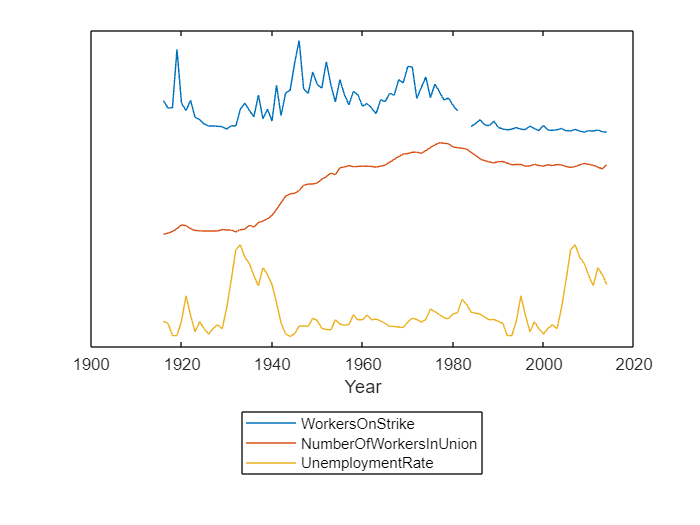

% Load the sample data
load('../data/union_data.mat', 'Y', 'X', 'Y_names', 'X_name', 'year')

% Plot the data over time 
plot(year, [Y, X])
stackplot
legend([Y_names, X_name],'Location','southoutside')
xlabel('Year')

Now we can compute the VARX model. We consider 'WorkersOnStrike' and 'NumberOfWorkersInUnion' as 'output' of the system y(t). They are also refered to as endogenous variables as they influcence each other. Later, in the context of neural data we will call these intrinsic variables. 'UnemploymentRate' is the 'input' to the system x(t). By definition the input is not affected by the output and by other input variables. For analysis of neural data we will also refer to inputs as extrinstic variables. 

% First set the parameters 
na = 3;         % Number of years for the potential effect of instrinsic effects on each other
nb = 3;         % Number of years to consider for external effects
lambda = 0;     % The regularization parameter lambda can control for overfitting

% Compute the VARX model
model = varx(Y,na,X,nb,lambda);

Let's examine the model! 

The VARX model estimates the effect B of the input variable 'UnemploymentRate' on each of the two endogenous variables. The filter B is of size nb x dy, where dy is the number of endogenous variables ('WorkersOnStrike' and 'NumberOfWorkersInUnion'). 

fprintf('Size of B: %d x %d\n', size(model.B))

Size of B: 3 x 2


The internal state of the system is modelled by the filter matrix A, which captures the effects of each intrinsic variable on each of the others. A is of size na x dy x dy. 

fprintf('Size of A: %d x %d x %d\n', size(model.A))

Size of A: 3 x 2 x 2


The computation of A and B filters comprises the system identification. The Granger formalism establishes whether the effect of any channel (extrinsic or intrinsic) on another is significant. This is achieved by comparing the full model to a model with one predictor removed (reduced model). The deviance and effect size R capture the magnitude of this effect, the p-value estimates the statistical significance.  

The model estimates the effect size R for the input variable on each endogenous variable:

fprintf('Size of B R-values: %d x %d\n', size(model.B_Rvalue))

Size of B R-values: 2 x 1


And between each endogenous variable:

fprintf('Size of A R-values: %d x %d\n', size(model.A_Rvalue))

Size of A R-values: 2 x 2


Looking at the effect of unemployment rate we see that it has a significant effect on the number of workers in unions, but not the number of workers on strike:

for i = 1:size(model.B_Rvalue,1)
    fprintf('%s -> %s: R = %1.3f, p = %1.3f\n', X_name{1}, Y_names{i}, model.B_Rvalue(i,1), model.B_pval(i,1))
end

UnemploymentRate -> WorkersOnStrike: R = 0.098, p = 0.829
UnemploymentRate -> NumberOfWorkersInUnion: R = 0.301, p = 0.035


Next, the model shows us the effects of the number of workers on strike and number of workers in unions on each other. The columns in the A matrix are the independent variables, i.e. the cause y(t-1); rows are the dependent variables, i.e. the effect on y(t). Diagonals are the autoregressive effects of variables on themselves. In the example, we see that the effect size of 'WorkersOnStrike' on 'NumberOfWorkersInUnion' (first column on second row), is larger than the effect of 'NumberOfWorkersInUnion' on 'WorkersOnStrike' (second column on first row). This is determined by the order of the variables in the array Y. 

for i = 1:size(model.A_Rvalue,2)
    for j = 1:size(model.A_Rvalue,1)
        if i~=j
            fprintf('%s -> %s: R = %1.3f, p = %1.3f\n', ...
                Y_names{i}, Y_names{j}, model.A_Rvalue(j,i), model.A_pval(j,i))
        end
    end
end

WorkersOnStrike -> NumberOfWorkersInUnion: R = 0.345, p = 0.009
NumberOfWorkersInUnion -> WorkersOnStrike: R = 0.294, p = 0.042


This model therefore supports the claim by Hodder et al., that strikes increase union membership. 

## Analysis of neural data

With some intuition of the VARX model we can delve into neural data. We will demonstrate the effects of the VARX model in comparison to mTRF on the data of one of the patients in Nentwich et al., 2025. The patient watched audiovisual movies during continuous recordings of intracranial EEG and eyetracking. 

### Setup

Download the data from OSF and define the path to the data directory:

data_dir = 'C:\Users\maxne\Documents\varx_tutorial_data';

% List all files
data_files = dir(sprintf('%s/recordings', data_dir));

% Remove directories
data_files([data_files.isdir]) = [];

### Load the data

In the first analysis all movies are concatenated. 

Not all movies have the same features. The 'Monkey' movies are silent. However, to get comparable filters when comparing movies, sound from other movies has been copied. 

% Select only movies (exclude 5 minute copy and resting state)
idx_movies = cellfun(@(C) ~contains(C, {'Despicable_Me_English_5min', 'Resting_fixation'}), {data_files.name});
movie_files = data_files(idx_movies);

% Create cell arrays to collect input arrays and data for multiple recordings
X = cell(length(movie_files), 1);
X_shift = cell(length(movie_files), 1);
Y = cell(length(movie_files), 1);

% Load all files 
for f = 1:length(movie_files)

    % For inscapes zeros are used for film cuts (the movie does not have cuts)
    if strcmp(movie_files(f).name, 'Inscapes.mat')

        load(sprintf('%s/recordings/%s', data_dir, movie_files(f).name), ...
            'lfp', 'hfa', 'fs', ...
            'fixations', 'fixation_novelty', 'audio_env', 'edge_vec')
    
        film_cuts = zeros(1, length(fixations));

    % For other movies all stimulus vectors are already processed
    else

        load(sprintf('%s/recordings/%s', data_dir, movie_files(f).name), ...
            'lfp', 'hfa', 'fs', ...
            'fixations', 'fixation_novelty', 'audio_env', 'edge_vec', 'film_cuts')
    
    end

    % Create the input array X by concatenating stimulus features in columns
    X{f} = [fixations, fixation_novelty, audio_env', edge_vec, film_cuts'];

    % Choose the neural signal of interest (HFA is also in the sample file and can be used in the same way)
    Y{f} = lfp;

    % Shift input vector for control analysis with unaligned features
    n_shift = round(length(X{f})/2);
    X_shift{f} = [X{f}(n_shift:end, :); X{f}(1:n_shift-1, :)];

end

% Name the input channels
x_names = {'Fixations', 'Fixation Novelty', 'Sound Envelope', 'Acoustic Edges', 'Film Cuts'};

% Load the channel labels and region of interest labels
load(sprintf('%s/channel_roi.mat', data_dir), 'roi')
load(sprintf('%s/channel_labels.mat', data_dir), 'labels')

### Compute the model

Using data in cell arrays the varx function can be called as above

% Model parameters
ta = 0.1;       % length of the VARX autoregressive filters A in seconds
tb = 0.6;       % length of the VARX input filter B in seconds
gamma = 0.3;    % Regularization parameter

% Compute filter length in samples
na = ta*fs;
nb = tb*fs;

% Compute the model
model_varx = varx(Y,na,X,nb,lambda);

time to compute correlations: 5.1716


### Visualize the input and recurrent filters

#### Input filters

% Construct the time vector
t = (0:nb-1) / fs;

% Number of input features
dx = size(model_varx.B,3); 

% Load custom colormap 
% From:
% Zhaoxu Liu / slandarer (2025). 200 colormap (https://www.mathworks.com/matlabcentral/fileexchange/120088-200-colormap), 
% MATLAB Central File Exchange. Retrieved August 15, 2025.
load('../src/cutsom_colormaps.mat', 'colormap_reds', 'colormap_bwr')

% Plot all input responses
figure('Position', [0,0,1350,500])

% Tiled layout with large space to adjust for colorbar in last figure
space = 50;
tiledlayout(1,space*dx+1)

for b = 1:dx

    % Get range to center around 0
    plt_max = max(max(abs(model_varx.B(:,:,b))));

    if b ~= dx, nexttile([1,space]), else, nexttile([1,space+1]), end

    imagesc([t(1), t(end)], [1, size(model_varx.B,2)], model_varx.B(:,:,b)')
    clim([-plt_max, plt_max])
    colormap(colormap_bwr)
    title(x_names{b})
    if b ~= 1, yticklabels([]), else, ylabel('Channel'), end
    if b == dx, c = colorbar; c.Label.String = 'B'; end
    xlabel('Input delay [s]')

end

fontsize(gcf(),14,'points')

The responses are mostly limited to a small number of channels. Below are plots of the input filters in channels with the largest effect size. 

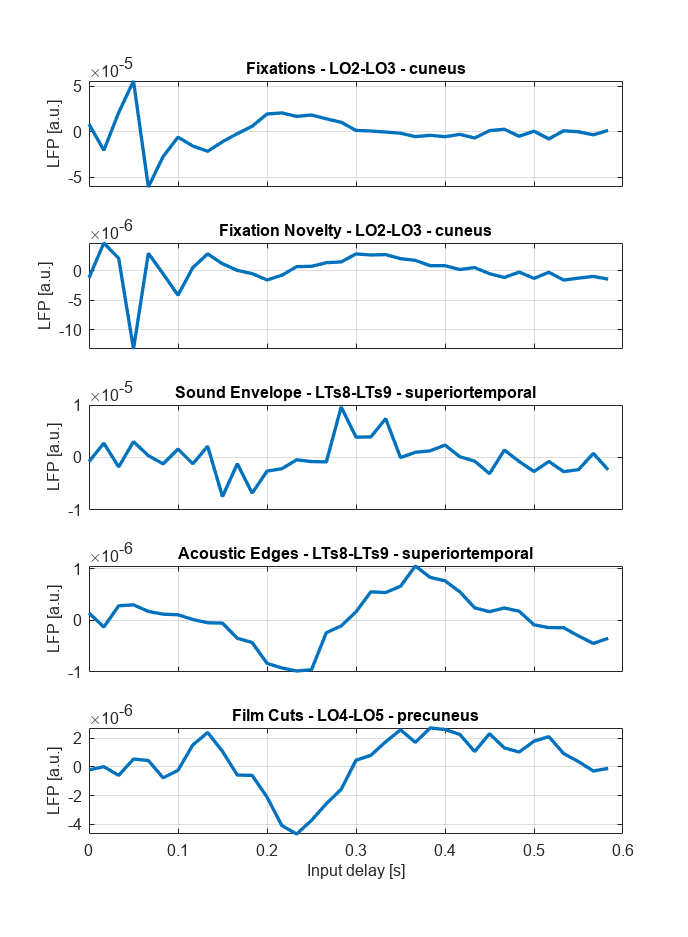

% Select the channels with the largest R value
[~, idx_max_B] = max(model_varx.B_Rvalue);

% Plot the input filters
figure('Position', [0,0,550,750])

for b = 1:dx
    subplot(dx,1,b)
    plot(t,model_varx.B(:,idx_max_B(b),b), 'LineWidth', 2)
    title(sprintf('%s - %s - %s', x_names{b}, labels{idx_max_B(b)}, roi{idx_max_B(b), 1}))
    if b ~= dx, xticklabels([]), else, xlabel('Input delay [s]'), end
    ylabel('LFP [a.u.]')
    grid on
end
fontsize(gcf(),10,'points')

The filters with the largest responses are in contacts in areas that are expected. Largest eye movement and film cut responses are in the cuneus and precuneus in the occipital cortex; sound responses in the superitemporal gyrus. 

Fixation novelty captures slower responses beyond 300ms that are not caputred by fixation onset. Acoustic edges caputre a larger part of the responses to sound (the sound envelope response is more noisy). 

#### Recurret dynamics

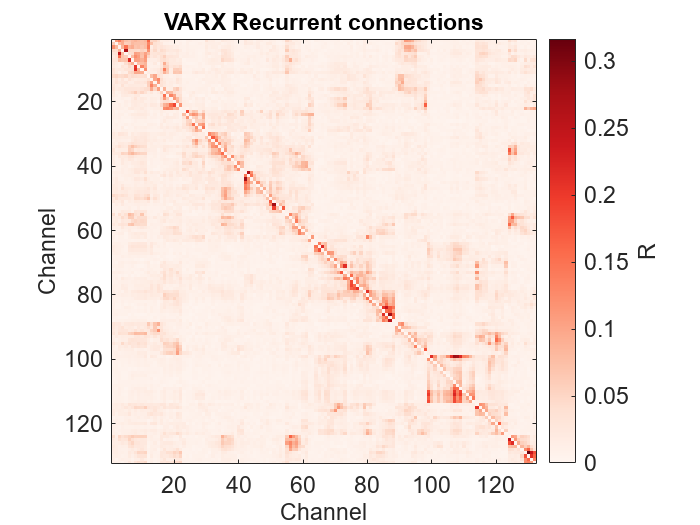

% Process the data for nicer plots
% The largest R values are on the diagonal, but those are not intersting 
AR = model_varx.A_Rvalue;
AR(eye(size(AR))==1) = 0;

figure()
imagesc(AR)
colormap(colormap_reds)
c = colorbar;
c.Label.String = 'R';
xlabel('Channel')
ylabel('Channel')
axis square
title('VARX Recurrent connections')
fontsize(gcf(),14,'points')

### Compare to the model without inputs

A VAR model without inputs has a different number of parameters so it is harder to compare. We shifted the input to get models comparable models with unaligned input, but perserving the model structure. 

model_var = varx(Y,na,X_shift,nb,lambda);

time to compute correlations: 5.5059


% The varx function can also be called without input, but to compare the
% two models it is better to preserve the statistics of the input
% model_var = varx(Y,na,[],0,lambda);

#### Plot the difference to the full VARX model with inputs

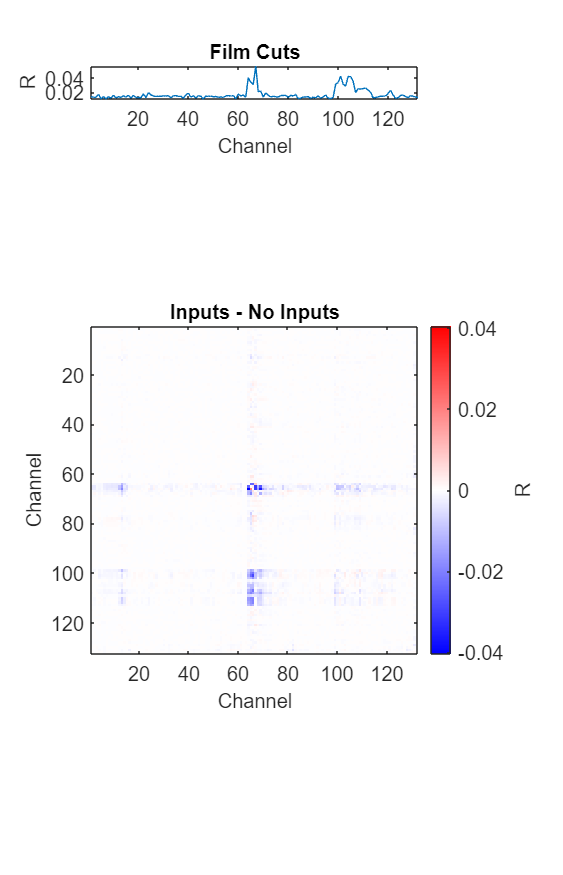

% Remove diagonal from VAR model
AR_var = model_var.A_Rvalue;
AR_var(eye(size(AR_var))==1) = 0;

% Difference
AR_diff = AR-AR_var;

% Find range to center coloraxis around zero
AR_diff_max = max(abs(AR_diff(:)));

% Figure
figure('Position', [0,0,450,700])
tiledlayout(6,1)

% Plot the R values for Film cuts (index 5)
nexttile
plot(model_varx.B_Rvalue(:,5))
if b ~= dx, xticklabels([]), else, xlabel('Channel'), end
ylabel('R')
xlim([1,size(model_varx.B_Rvalue,1)])
title(x_names{5})

nexttile([5,1])

% Plot the difference in R values for the A matrices
imagesc(AR_diff)
clim([-AR_diff_max, AR_diff_max])
colormap(colormap_bwr)
c = colorbar;
c.Label.String = 'R';
xlabel('Channel')
ylabel('Channel')
axis square
title('Inputs - No Inputs')
fontsize(gcf(),12,'points')

The blue channel pairs show a decrease in effect size when external inputs are included in the model. Two different clusters of channels show responses to visual inputs, such as film cuts (64-69 in the cuneus and 99-113 in the lateraloccipital cortex). If visual inputs are not included in the model these two clusters would show a strong spurious connection to each other (in particular from the cuneus to the lateraloccipital cortex). 

### Comparison of VARX input filters B to TRFs

The input filters of the VARX model can be used similar to TRFs. However, the VARX model removes the effects of reccurent connections between channels in the neural data from the input response. 

Here we derive the total system response (TRF) from the VARX model. The total system response H is the impulse response of the total system consisting of the input filter B and the recurrent filter A. This corresponds to a TRF.

% Total system response
TRF = varx_trf(model_varx.B, model_varx.A, nb);

#### Visualize the input filters B and total system response H

% Plot the input filters B and total system response for all channels
figure('Position', [0,0,1350,1000])

space = 50;
tiledlayout(2,space*dx+1)

% Get the range for B and H 
plt_max = zeros(2,dx);
for b = 1:dx
    plt_max(1,b) = max(max(abs(model_varx.B(:,:,b))));
    plt_max(2,b) = max(max(abs(TRF(:,:,b))));
end
plt_max = max(plt_max);

% Plot the input filters B as above
for b = 1:dx

    if b ~= dx, nexttile([1,space]), else, nexttile([1,space+1]), end

    imagesc([t(1), t(end)], [1, size(model_varx.B,2)], model_varx.B(:,:,b)')
    clim([-plt_max(b), plt_max(b)])
    colormap(colormap_bwr)
    title(sprintf('B - %s', x_names{b}))
    if b ~= 1, yticklabels([]), else, ylabel('Channel'), end
    if b == dx, c = colorbar; c.Label.String = 'B'; end

end

% Add the total system response below on the same range

for b = 1:dx

    if b ~= dx, nexttile([1,space]), else, nexttile([1,space+1]), end

    imagesc([t(1), t(end)], [1, size(TRF,2)], TRF(:,:,b)')
    clim([-plt_max(b), plt_max(b)])
    colormap(colormap_bwr)
    title(sprintf('TRF - %s', x_names{b}))
    if b ~= 1, yticklabels([]), else, ylabel('Channel'), end
    if b == dx, c = colorbar; c.Label.String = 'H'; end
    xlabel('Input delay [s]')

end

fontsize(gcf(),12,'points')

### Analyze asymetry of connections

The main goal of Granger analysis is to investiage the directionaliy of connecitons. In neural data that would indicate potential information flow from one recording location to another. In our example we can estimate directionality by looking at the difference of R values for two channels in each direction, i.e. Channel A -> Channel B versus Channel B -> Channel A. 

A quick way to visualize this is to subtract the transpose of the effect size matrix of A from the original matrix. 

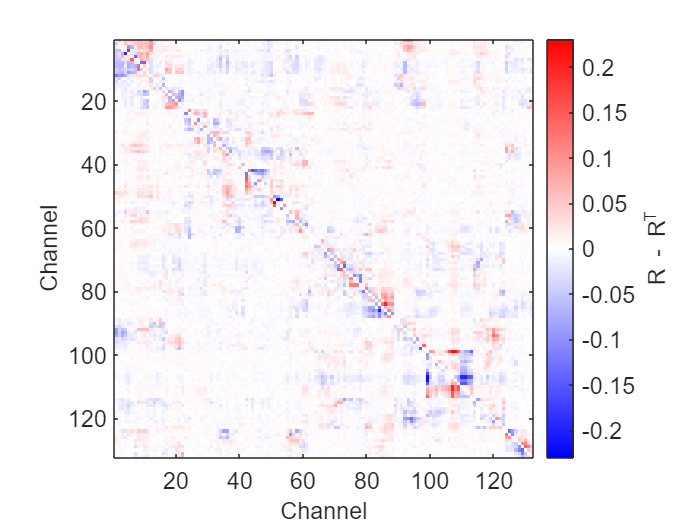

% Subtract the transpose effect size matrix from the original
AT = model_varx.A_Rvalue - model_varx.A_Rvalue';

% Plot
figure

imagesc(AT)
colormap(colormap_bwr)
c = colorbar();
c.Label.String = 'R - R^T';
axis square
xlabel('Channel')
ylabel('Channel')
fontsize(gcf(),14,'points')

#### ROI based analysis

Many of these connecitons have small p-values. These are confirmed for directed connections with permutation statistics as below. This may be sufficient if the focus of analysis is a specific connection. In intracranial EEG there can be large differences in nearby channels and for more confidence channels can be grouped in regions of interest (ROI). This also allows to combine channels across patients with heterogenuous coverage. 

This example demonstrates how to group channels in a ROI and test whether a ROI has more incoming or outgoing connections on average. 

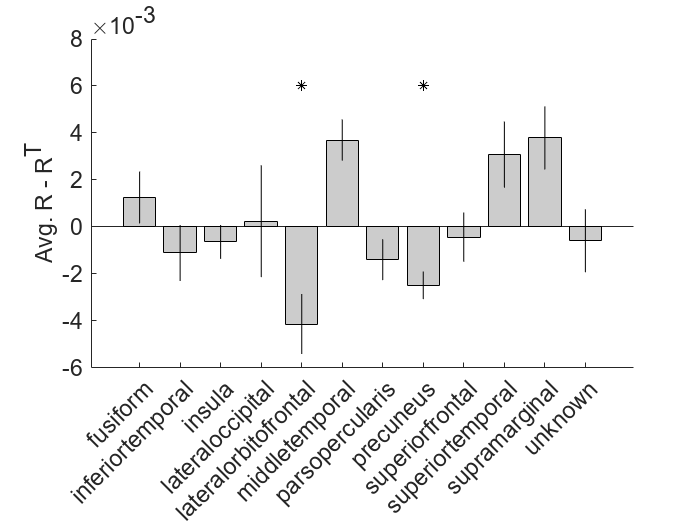

% ROI labels for this patient has been loaded before
% Since a bipolar montage was used each channel has one label for each of the two contacts in a channel pair.
% Channels at the boundary between two ROIs are difficult to attribute. 
% In this example, for simplicity, only the ROI of the first contact is used. 

% Find all unique ROIs
rois = unique(roi(:,1));

% Count how many channels are in each ROI
n_ch_roi = zeros(length(rois), 1);
for i = 1:length(rois)
    n_ch_roi(i) = sum(cellfun(@(C) strcmp(C, rois{i}), roi(:,1)));
end

% Filter by minimum number of channels
ch_min = 5;

idx_ch = n_ch_roi > ch_min;
rois = rois(idx_ch);
n_ch_roi = n_ch_roi(idx_ch);


% Each column of the asymetry matrix 'AT' represents a channels effect on
% all other channels. An average positive value would indicate a net
% 'outflow', a negative value a net 'inflow'

% Allocate cells and arrays for data in each ROI
asym_roi = cell(length(rois), 1);
p_asym = zeros(length(rois), 1);
h_asym = zeros(length(rois), 1);
sem_asym = zeros(length(rois), 1);

% Get degree of inflow/outflow by ROI
for i = 1:length(rois)

    % Get the asymetry by averaging across each columg
    asym_roi{i} = mean(AT(:,cellfun(@(c) strcmp(c, rois{i}), roi(:,1))));

    % Test whether the asymetry is different than zero across channels 
    [p_asym(i), h_asym(i)] = signrank(asym_roi{i});

    % Compute the standard error of the mean (SEM)
    sem_asym(i) = std(asym_roi{i}) / sqrt(length(asym_roi));

end

% Plot
figure
hold on

% Bar plot of the mean asymetry per ROI
bar(cellfun(@(C) mean(C), asym_roi), 'FaceColor',[0.8,0.8,0.8])
b_lim = ylim();

for r = 1:length(rois)

    % Plot the SEM
    plot([r,r], mean(asym_roi{r}) + sem_asym(r)*[-1,1], 'k')

    % Indicate ROIs with significant asymetry across channels
    if p_asym(r) < 0.05
        plot(r, 1.5*b_lim(2), 'k*')
    end

end

xticks(1:length(rois))
xticklabels(rois)
xtickangle(45)
ylabel('Avg. R - R^T')

fontsize(gcf(),14,'points')

Postive values indicate 'outflow', i.e. connectivity that is stronger origination from the region of interest; negative values indicate 'inflow', i.e. connectivity that is stronger towards the region of interest.

In this example the lateral orbitofrontal cortex and precuneus have significant net inflow from other channels. 

Note that these results depend on the specific converage for a given patient. Any analysis in iEEG data will need to combine data across patients, or limit the ROIs. 

#### Permutation testing for a channel of interest

Whether a specific connection is stronger in one direction than the other can also be tested with permutation statitics. One option is to use a circular shuffle of the time series of the channel of interest to get a surrogate distribution of the direction of the connection.  

% Compute permutations

% This is slow so was saved to a file
perm_file = '../data/varx_perm.mat';

if exist(perm_file, 'file') == 0

    % Define the channel to permute and number of permutations
    ch_perm = 93;
    n_perm = 100;
    
    % Define arrays for the permuted effect size asymetry matrices (A - A^T)
    model_varx_perm = cell(n_perm,1);
    AT_perm = zeros(size(AT,1), size(AT,2), n_perm);
    
    % Permute
    for n = 1:n_perm
    
        fprintf('%d\n', n);
    
        % Permute neural data
        Y_perm = cell(length(Y),1);
        for r = 1:length(Y)
            idx_perm = randi(size(Y{r},1));
            Y_perm{r} = Y{r};
            Y_perm{r}(:,ch_perm) = [Y{r}(idx_perm:end, ch_perm); Y{r}(1:idx_perm-1, ch_perm)];
        end
    
        % Compute the surrogate model
        model_varx_perm{n} = varx(Y_perm,na,X,nb,lambda);

        % Compute the asymetry matrix
        AT_perm(:,:,n) = model_varx_perm{n}.A_Rvalue - model_varx_perm{n}.A_Rvalue';
    
    end

    % SAve the data
    save(perm_file, 'AT_perm', 'ch_perm', 'n_perm')

else
    load(perm_file, 'AT_perm', 'ch_perm', 'n_perm')
end

With this surrogate data we can test the significance of a conneciton. 

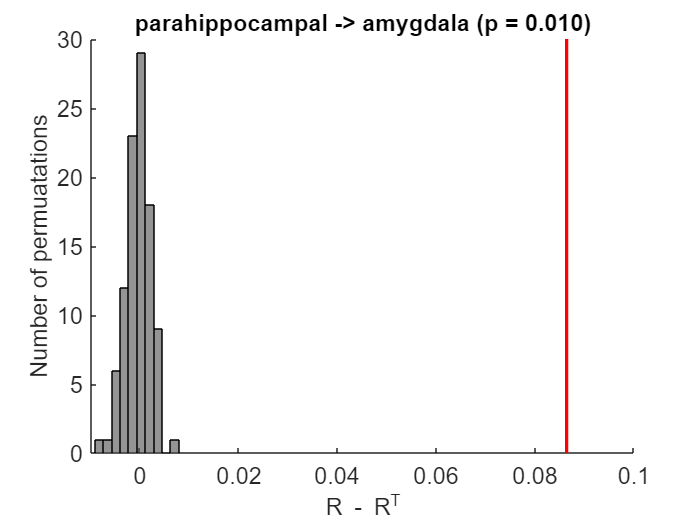

% Define the 'source' and 'target' channels
ch_target = 3;
ch_source = 93;

% Compute a p-value, i.e. mean of surrogate values larger than the acutal effect size of the connection 
p_val = sum(squeeze(AT_perm(ch_target,ch_source,:)) > AT(ch_target,ch_source)) / n_perm;

% The smallest possible p-value depends on the number of permutations
if p_val == 0, p_val = 1/n_perm; end

% Plot a histogram
figure()
hold on

histogram(squeeze(AT_perm(ch_target,ch_source,:)), 10, 'FaceColor',[0.3,0.3,0.3])
h_ylim = ylim();
plot(AT(ch_target,ch_source)*ones(2,1), h_ylim, 'r', 'LineWidth',2)
title(sprintf('%s -> %s (p = %1.3f)', roi{ch_source,1}, roi{ch_target,1}, p_val))
xlabel('R - R^T')
ylabel('Number of permuatations')
ylim(h_ylim)
fontsize(gcf(),14,'points')

## References

Hodder, Andy, et al. "Does strike action stimulate trade union membership growth?." *British Journal of Industrial Relations* 55.1 (2017): 165-186.

Parra, Lucas C., et al. "VARX Granger analysis: Models for neuroscience, physiology, sociology and econometrics." *PloS one* 20.1 (2025): e0313875.

Nentwich, Maximilian, et al. "Intrinsic dynamic shapes responses to external stimulation in the human brain." *eLife* 14 (2025): RP104996.